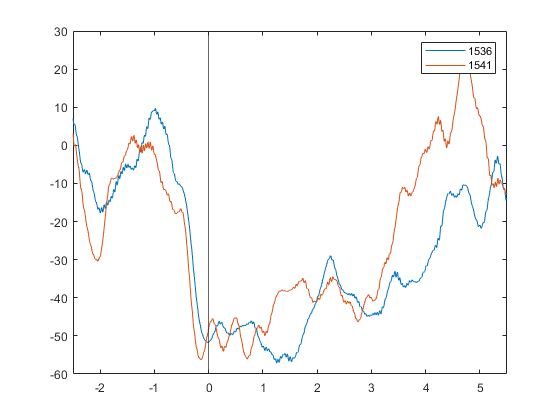

%[grand_mean_mu_1541,grand_mean_beta_1541,ERD_mu_1541,ERD_beta_1541] = D6_function(1541,[false,false],subject_list,data,icadata);
%[grand_mean_mu_1536,grand_mean_beta_1536,ERD_mu_1536,ERD_beta_1536] = D6_function(1536,[false,false],subject_list,data,icadata);

figure
t=-2.5+1/512:1/512:5.5;
plot(t,grand_mean_mu_1536(28,:))
hold on 
plot(t,grand_mean_mu_1541(28,:))
xline(0);xlim([-2.5 5.5])
legend('1536','1541')

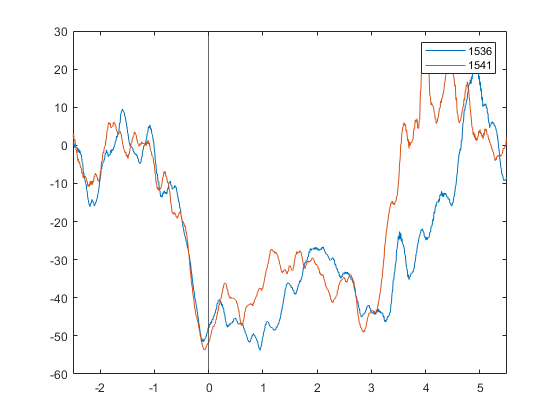

figure
plot(t,grand_mean_beta_1536(28,:))
hold on 
plot(t,grand_mean_beta_1541(28,:))
xline(0);xlim([-2.5 5.5]);
legend('1536','1541')

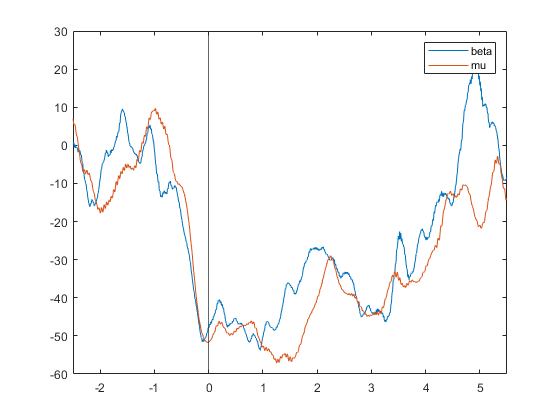

figure
plot(t,grand_mean_beta_1536(28,:))
hold on 
plot(t,grand_mean_mu_1536(28,:))
xline(0);xlim([-2.5 5.5]);
legend('beta','mu')

eeglab;close;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\vctrf\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


waitfor(msgbox("Now, please select your loc file without EOG channels", 'Loc file selection'));
[locs_noica,locpath_noica]=uigetfile('*.loc', 'Pick a channel location file');
locpath_noica=strrep(locpath_noica,'\','\\'); %for windows
locs_noica=append(locpath_noica,locs_noica);

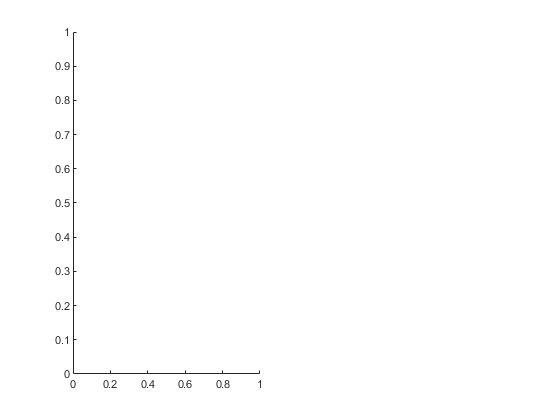

readlocs(): 'loc' format assumed from file extension


Index exceeds the number of array elements. Index must not exceed 61.

Error in topoplot (line 760)
    Values      = Values(plotchans);

Error in D7_topoplots (line 7)
topoplot(squeeze(potentials),locs,'maplimits',[-60 0]);

H1=figure(10);
subplot(1,2,1)
D7_topoplots(grand_mean_mu_1536,locs);

subplot(1,2,2)
D7_topoplots(grand_mean_mu_1541,locs);
set(H1,'Position',[10 10 2000 750]);

H2=figure(11);
subplot(1,2,1)
D7_topoplots(grand_mean_beta_1536,locs);
subplot(1,2,2)
D7_topoplots(grand_mean_beta_1541,locs);
set(H2,'Position',[10 10 2000 750]);
